## SIOC 221A HW 1

## Kevin Okun

### Problem 1

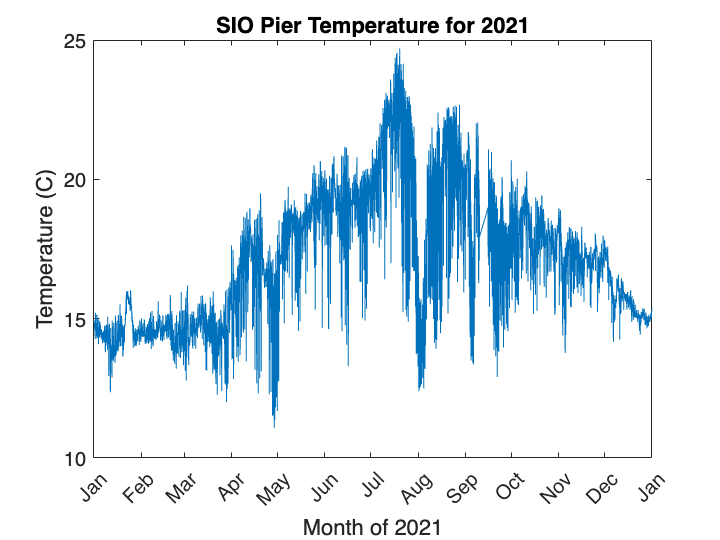

% Create reference date for time vector
date0=datenum(1970,1,1);

% Load time and temp data from SCCOOS site
SIO_Pier_2021.time=double(ncread('http://sccoos.org/thredds/dodsC/autoss/scripps_pier-2021.nc','time'))/3600/24+date0;
SIO_Pier_2021.temperature=ncread('http://sccoos.org/thredds/dodsC/autoss/scripps_pier-2021.nc','temperature');

% Plot temperature vs time for 2021 and label
figure(101)
plot(SIO_Pier_2021.time,SIO_Pier_2021.temperature)
datetick('x','mmm')
ylabel('Temperature (C)')
xlabel('Month of 2021')
title('SIO Pier Temperature for 2021')

In this plot, we see a similar pattern to the time series we looked at in class. There is a peak in water temperature in the summer, accompanied by more significant variability than in winter. As mentioned in class, this is likely due a deeper mixed layer at the end of the pier, were the thermocline may not even reach since it is too deep for the bathymetry. There is a significant upwelling period in August that dropped the temperature to winter levels.

% Calculate mean and standard deviation for 2021 and print results
SIO_Pier_2021.temp_mean = mean(SIO_Pier_2021.temperature,'omitnan');
SIO_Pier_2021.temp_std = std(SIO_Pier_2021.temperature,'omitnan');

disp(['The mean temperature for 2021 is ', num2str(SIO_Pier_2021.temp_mean), 'C'])

The mean temperature for 2021 is 17.274C


disp(['The standard deviation of temperature for 2021 is ',num2str(SIO_Pier_2021.temp_std), 'C'])

The standard deviation of temperature for 2021 is 2.4254C


The mean, if taken over multiple years, can be an indicator of long-term changes, acting as a low-pass filter. Variability is measured by the standard deviation and could also be tracked over years. Both of these values could give different insights if taken over smaller bins, such as seasonally or monthly.

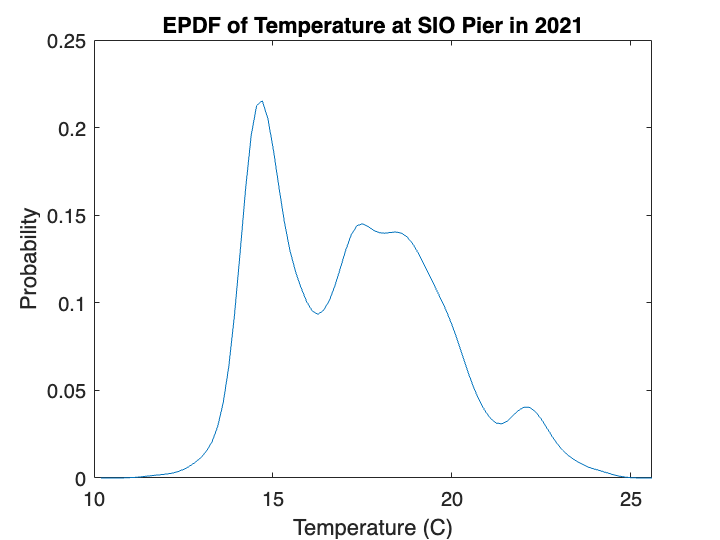

% Calculate and plot epdf of temperature in 2021
[SIO_Pier_2021.epdf,SIO_Pier_2021.epdf_temps] = ksdensity(SIO_Pier_2021.temperature);

figure(102)
plot(SIO_Pier_2021.epdf_temps,SIO_Pier_2021.epdf)
ylabel('Probability')
xlabel('Temperature (C)')
title('EPDF of Temperature at SIO Pier in 2021')

The EPDF of 2021 is not very similar to the distributions that we saw in class so far. There is a complex peak structure and the temperatures have a tail on the high end. The lower temperature peak is relatively narrow, and corresponds to the lower-variability winter temperature.

### Problem 2

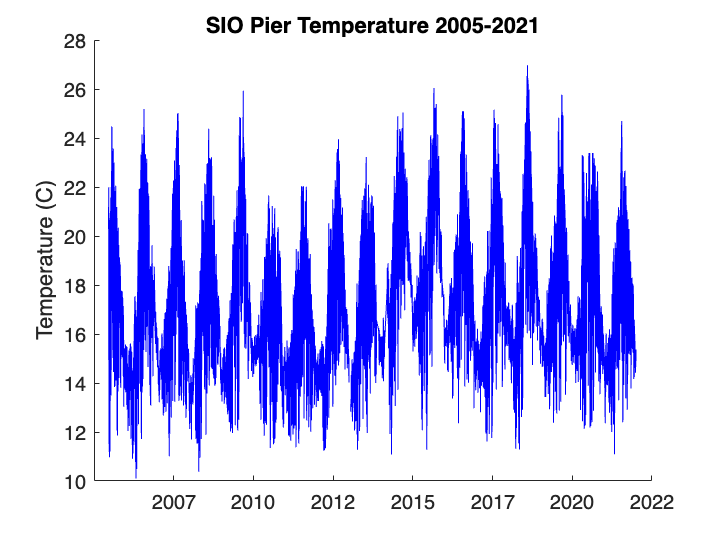

% Define date range
pier.date_range = 2005:2021;

% Plot setup
pier.legend_string = strings(1,length(pier.date_range));

figure(201)
clf
hold on
ylabel('Temperature (C)')
title('SIO Pier Temperature 2005-2021')

figure(202)
clf
hold on
ylabel('Probability')
xlabel('Temperature (C)')
title('EPDF of Temperature at SIO Pier 2005-2021')

% Looping through each year and loading data
for idx = 2005:2021
    pier.legend_string((idx-2004)) = num2str(idx);
    pier.(['year_',num2str(idx)]).filename = (['http://sccoos.org/thredds/dodsC/autoss/scripps_pier-',num2str(idx),'.nc']);
    pier.(['year_',num2str(idx)]).temperature = filloutliers(ncread(pier.(['year_',num2str(idx)]).filename,'temperature'),'linear');
    pier.(['year_',num2str(idx)]).time = double(ncread(pier.(['year_',num2str(idx)]).filename,'time'))/3600/24+date0;

    % Plot temperature vs time
    figure(201)
    plot(pier.(['year_',num2str(idx)]).time,pier.(['year_',num2str(idx)]).temperature,'b')
    
    % Calculate mean and std
    pier.(['year_',num2str(idx)]).temp_mean = mean(pier.(['year_',num2str(idx)]).temperature,'omitnan');
    pier.(['year_',num2str(idx)]).temp_std = std(pier.(['year_',num2str(idx)]).temperature,'omitnan');

%     disp(['The mean temperature for ',num2str(idx), 'is ', num2str(pier.(['year_',num2str(idx)]).temp_mean), 'C'])
%     disp(['The standard deviation of temperature for ',num2str(idx), 'is ',num2str(pier.(['year_',num2str(idx)]).temp_std), 'C'])

    % Calculate EPDF
    [pier.(['year_',num2str(idx)]).epdf,pier.(['year_',num2str(idx)]).epdf_temps] = ksdensity(pier.(['year_',num2str(idx)]).temperature);
    
    % Plot EPDF for all years in range
    figure(202)
    plot(pier.(['year_',num2str(idx)]).epdf_temps,pier.(['year_',num2str(idx)]).epdf)
end

figure(201)
datetick('x','yyyy')

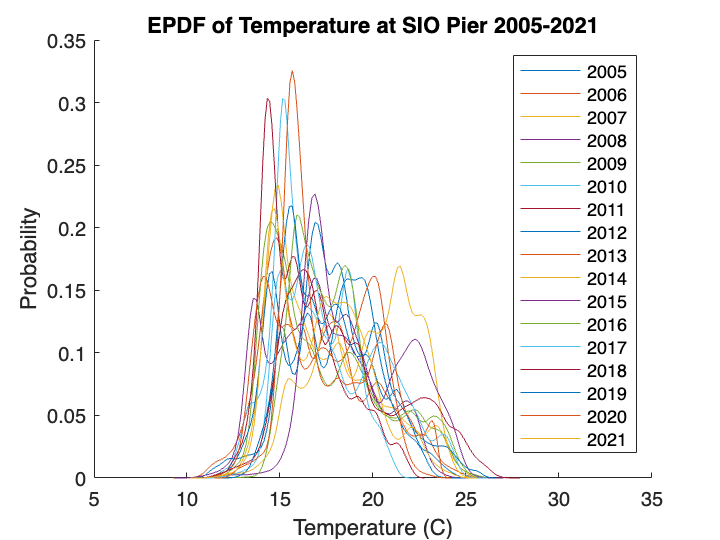


figure(202)
legend(pier.legend_string)
xlim([5 35])


clearvars date0 idx file

Over the timeseries, the temperature goes through similar cycles as the 2021 example above. We can start to see some more long timescale variations in the temperature now, with some years more variable than others. Looking at the epdfs of each year, they fall roughly within the same range, with some variations to peak distributions and shifts along the axis. Both 2021 and 2016 appear to fit well within the range of values within this time series, so I'd say that they are not that irregular.